# Noisy Signal

Find the frequency components of a signal buried in noise and find the amplitudes of the peak frequencies by using Fourier transform.

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

Form a signal containing a DC offset of amplitude 0.8, a 50 Hz sinusoid of amplitude 0.7, and a 120 Hz sinusoid of amplitude 1.

S = 0.8 + 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

Corrupt the signal with zero-mean random noise with a variance of 4.

X = S + 2*randn(size(t));

Plot the noisy signal in the time domain. The frequency components are not visually apparent in the plot.

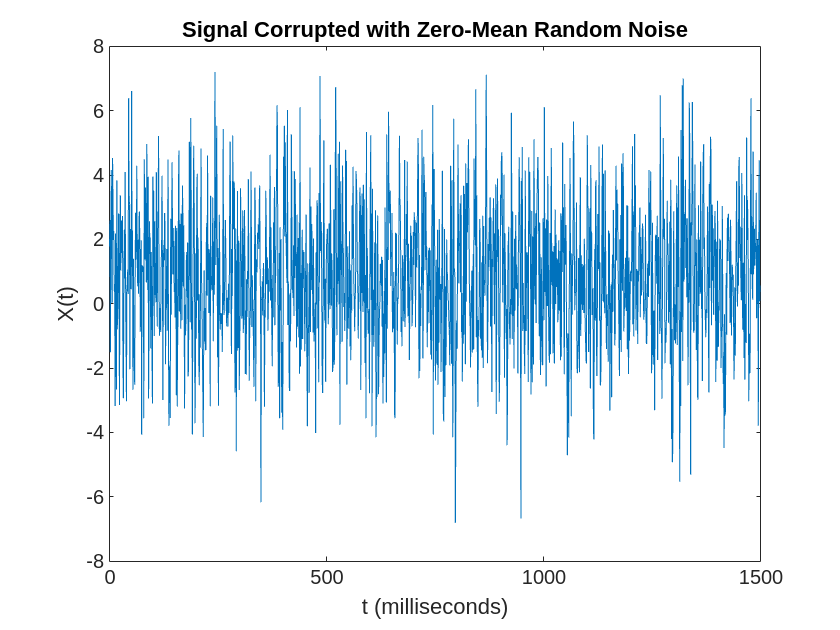

plot(1000*t,X)
title("Signal Corrupted with Zero-Mean Random Noise")
xlabel("t (milliseconds)")
ylabel("X(t)")

Compute the Fourier transform of the signal. 

Y = fft(X)

Y = 1.0e+03 *

   1.2691 + 0.0000i   0.0292 - 0.0005i   0.0501 + 0.0050i   0.0593 + 0.0057i  -0.0191 - 0.0270i   0.0358 - 0.0566i   0.0222 + 0.0205i  -0.0236 - 0.0744i   0.0050 + 0.0071i   0.0711 - 0.1588i  -0.0123 + 0.1449i   0.1462 + 0.0042i   0.0215 + 0.0679i  -0.0344 + 0.0365i  -0.0525 + 0.0647i  -0.0024 + 0.0318i  -0.0218 + 0.0738i   0.0063 - 0.0274i   0.0539 + 0.0486i  -0.0113 - 0.1160i  -0.0145 + 0.0549i  -0.0387 - 0.0383i  -0.0558 - 0.0093i  -0.0314 - 0.0013i   0.0229 - 0.0482i   0.0852 + 0.0023i   0.1141 - 0.0901i   0.0679 + 0.0596i   0.0574 + 0.0399i  -0.0143 + 0.0481i  -0.0800 + 0.1181i   0.0410 - 0.0028i   0.0488 - 0.0469i   0.0159 - 0.0259i  -0.0668 + 0.0215i  -0.0150 + 0.0122i  -0.0144 + 0.0791i   0.0614 + 0.0211i   0.0413 - 0.0015i  -0.0377 - 0.0019i   0.0688 - 0.1425i  -0.0342 - 0.0293i   0.0425 + 0.0366i  -0.0319 + 0.0605i  -0.0418 + 0.0199i   0.0268 - 0.1254i  -0.0370 + 0.0986i  -0.0480 + 0.0584i  -0.0042 + 0.0260i   0.0102 - 0.0286i


Because Fourier transforms involve complex numbers, plot the complex magnitude of the `fft` spectrum.

Fs/L*(0:L-1)

ans =          0    0.6667    1.3333    2.0000    2.6667    3.3333    4.0000    4.6667    5.3333    6.0000    6.6667    7.3333    8.0000    8.6667    9.3333   10.0000   10.6667   11.3333   12.0000   12.6667   13.3333   14.0000   14.6667   15.3333   16.0000   16.6667   17.3333   18.0000   18.6667   19.3333   20.0000   20.6667   21.3333   22.0000   22.6667   23.3333   24.0000   24.6667   25.3333   26.0000   26.6667   27.3333   28.0000   28.6667   29.3333   30.0000   30.6667   31.3333   32.0000   32.6667


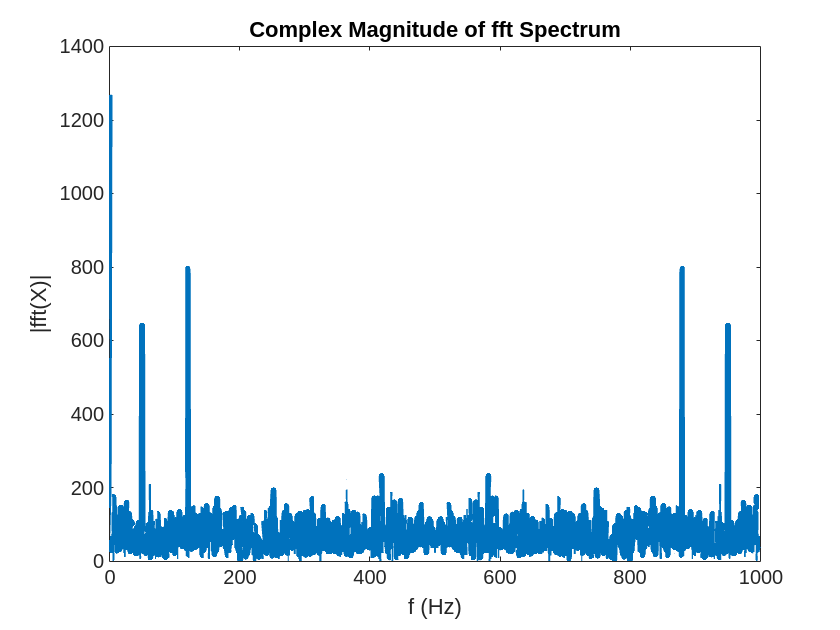


plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

The plot shows five frequency peaks including the peak at 0 Hz for the DC offset. In this example, the signal is expected to have three frequency peaks at 0 Hz, 50 Hz, and 120 Hz. Here, the second half of the plot is the mirror reflection of the first half without including the peak at 0 Hz. The reason is that the discrete Fourier transform of a time-domain signal has a periodic nature, where the first half of its spectrum is in positive frequencies and the second half is in negative frequencies, with the first element reserved for the zero frequency.

For real signals, the `fft` spectrum is a two-sided spectrum, where the spectrum in the positive frequencies is the complex conjugate of the spectrum in the negative frequencies. To show the `fft` spectrum in the positive and negative frequencies, you can use `fftshift`. For an even length of `L`, the frequency domain starts from the negative of the Nyquist frequency `-Fs/2` up to `Fs/2-Fs/L` with a spacing or frequency resolution of `Fs/L`.

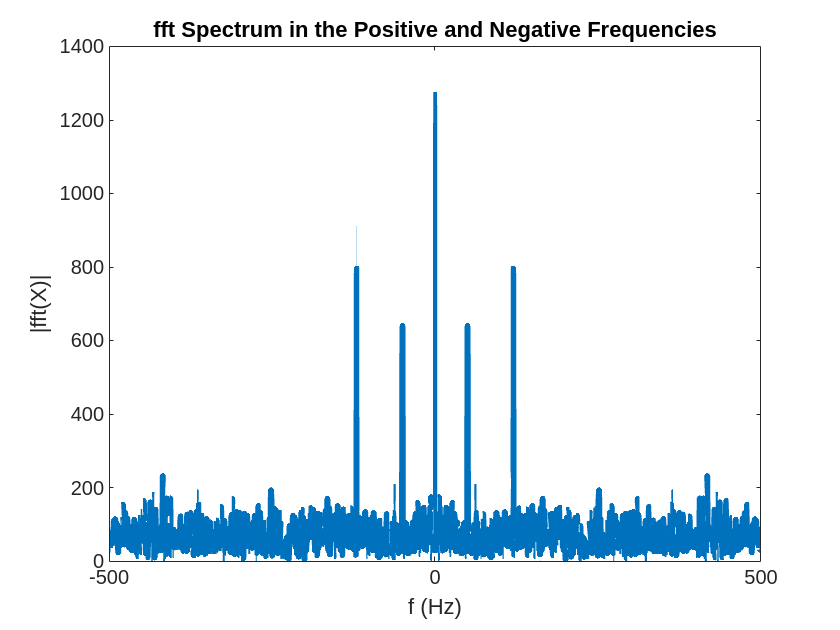

plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)),"LineWidth",3)
title("fft Spectrum in the Positive and Negative Frequencies")
xlabel("f (Hz)")
ylabel("|fft(X)|")

To find the amplitudes of the three frequency peaks, convert the `fft` spectrum in `Y` to the single-sided amplitude spectrum. Because the `fft` function includes a scaling factor `L` between the original and the transformed signals, rescale `Y` by dividing by `L`. Take the complex magnitude of the `fft` spectrum. The two-sided amplitude spectrum `P2`, where the spectrum in the positive frequencies is the complex conjugate of the spectrum in the negative frequencies, has half the peak amplitudes of the time-domain signal. To convert to the single-sided spectrum, take the first half of the two-sided spectrum `P2`. Multiply the spectrum in the positive frequencies by 2. You do not need to multiply `P1(1)` and `P1(end)` by 2 because these amplitudes correspond to the zero and Nyquist frequencies, respectively, and they do not have the complex conjugate pairs in the negative frequencies.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain `f` for the single-sided spectrum. Plot the single-sided amplitude spectrum `P1`. As expected, the amplitudes are close to 0.8, 0.7, and 1, but they are not exact because of the added noise. In most cases, longer signals produce better frequency approximations.

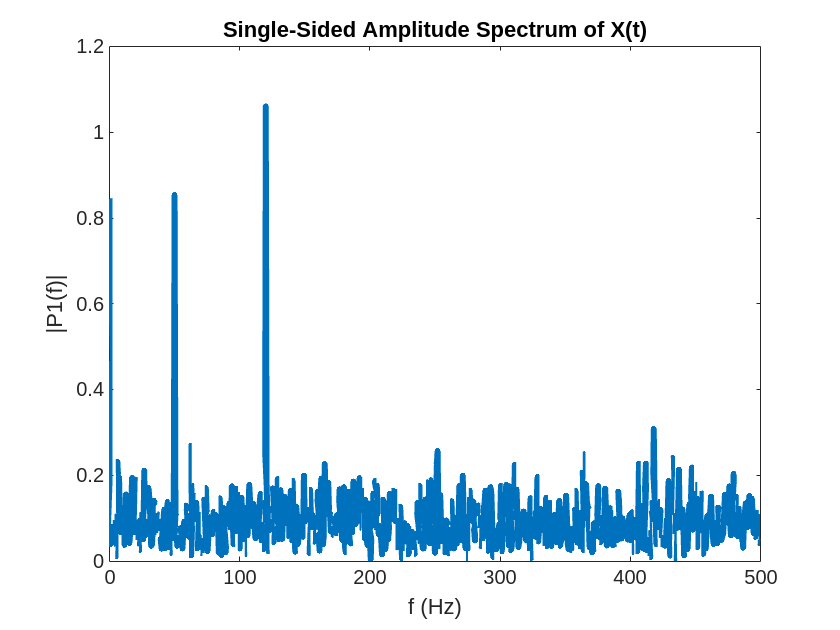

f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",3) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

Now, take the Fourier transform of the original, uncorrupted signal and retrieve the exact amplitudes at 0.8, 0.7, and 1.0.

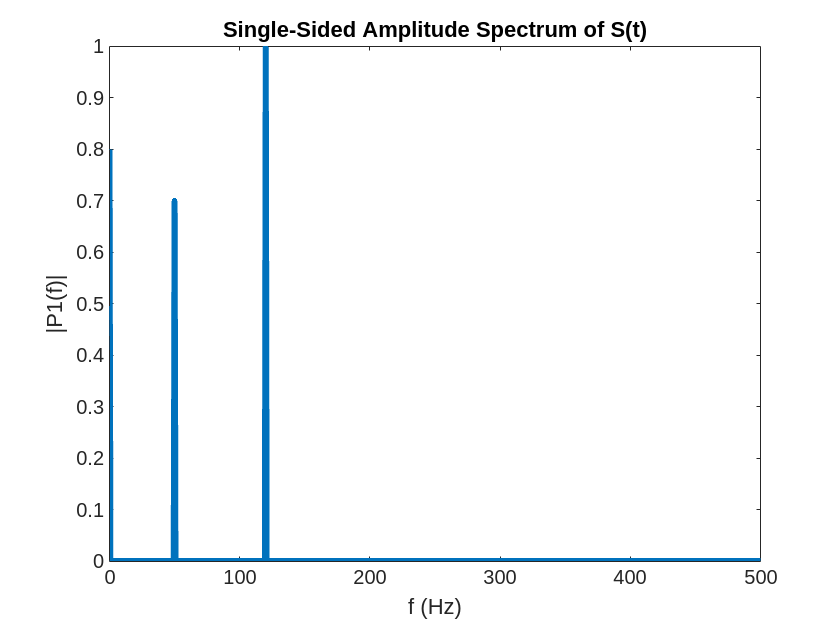

Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1,"LineWidth",3) 
title("Single-Sided Amplitude Spectrum of S(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

**https://la.mathworks.com/help/matlab/ref/fft.html**

*Copyright 2012 The MathWorks, Inc.*